Ejemplo de diseño y aplicación de filtros digitales

Inicialmente se cre una señal de prueba con varios armónicos para observar el desempñeo de los filtros

También se calcula su espcetro de frecuencia usando la FFT

n=0:511;% vector de tiempo
k=n/512;% vector de frecuencias
xn=sin(2*pi*n*1/4)+sin(2*pi*n*1/8)+sin(2*pi*n*1/32)+sin(2*pi*n*1/128);
xk=abs(fft(xn));

Se grafican la señal y su respectivo espectro de frecuencia

Identifique cada frecuancia y su ubicación en el dominio de la frecuencia

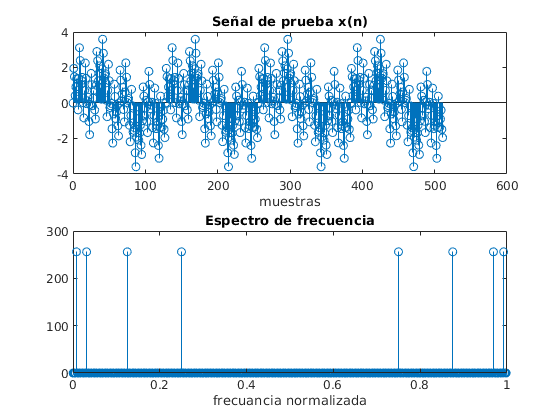

figure()
subplot(2,1,1);
stem(n,xn);
xlabel('muestras')
title('Señal de prueba x(n)');
subplot(2,1,2);
stem(k,xk);
xlabel('frecuancia normalizada')
title('Espectro de frecuencia');

Se crea un filtro pasa-bajos digital utilizando el método de Butterworth. Mediante la función butter se obtienen los coeficientes de la función de transferencia del filtro.

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


Observe las unidades de frecuencia que utiliza matlab

[b1,a1]=butter(3,1/16);

A continuación se grafica la respuesta en frecuencia del filtro mediante el comando freqz. Como se trata de un filtro iir, note que se tienen valores diferentes de 1 para el denominador de la función de transferencia

Haciendo zoom sobre la figura, trate de ubicar el punto más cercano a la frecuencia de corte (ganancia -3 dB)

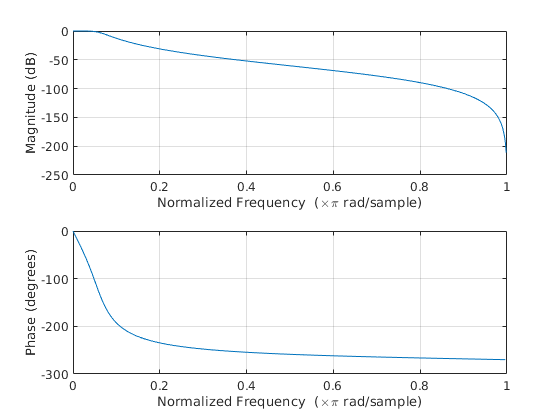

figure();
freqz(b1,a1);

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(b1,a1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

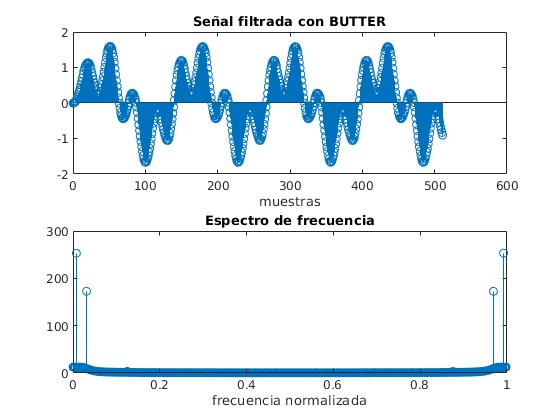

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con BUTTER');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

Para la siguiente parte del ejemplo se aplicará el método de diseño de filtros IIR Chebyshev. Existen dos tipos (1 y 2) que se diferencian en la banda que presenta rizado

Este método de diseño se aplica mediante la función cheby1

[b2,a2]=cheby1(3,0.5,1/16);

Se aplica el filtro usando filter y se obtiene la representación en frecuencia de la señal filtrada usando la FFT.

Freqz permite ver la respuesta en frecuancia del filtro (ganancia y fase)

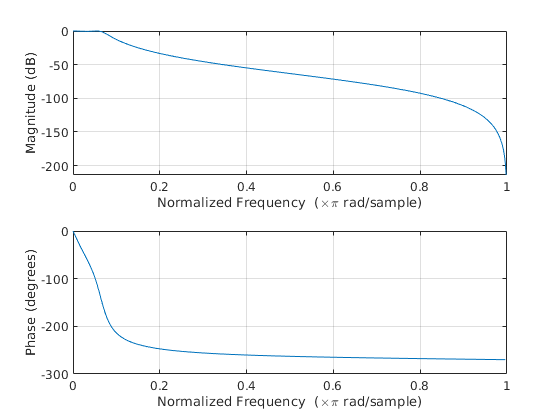

y2n=filter(b2,a2,xn);
y2k=abs(fft(y2n));
figure();
freqz(b2,a2);

Se grafican los resultados. Compare con las señales originales e identifique los cambios.

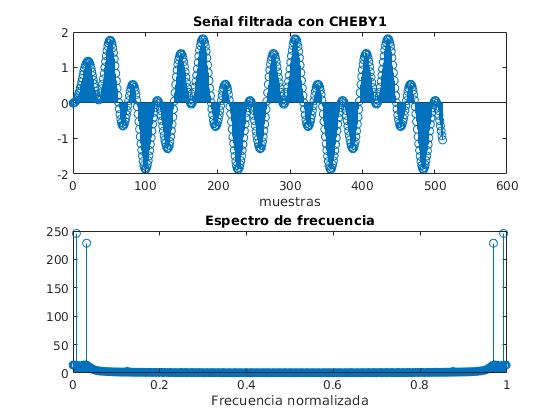

figure()
subplot(2,1,1);
stem(n,y2n);
xlabel('muestras')
title('Señal filtrada con CHEBY1');
subplot(2,1,2);
stem(k,y2k);
xlabel('Frecuencia normalizada')
title('Espectro de frecuencia');

Ahora se aplica el segundo método de Chebyshev

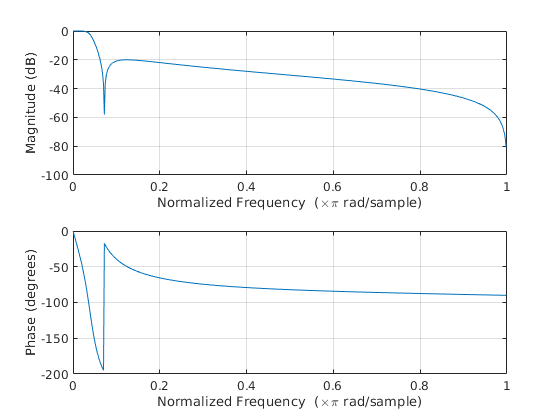

[b3,a3]=cheby2(3,20,1/16);
y3n=filter(b3,a3,xn);
y3k=abs(fft(y3n));
figure();
freqz(b3,a3);

Graficación de los resultados

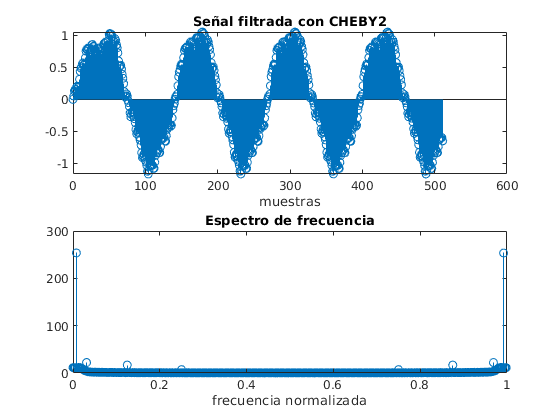

figure()
subplot(2,1,1)
stem(n,y3n);
xlabel('muestras')
title('Señal filtrada con CHEBY2');
subplot(2,1,2);
stem(k,y3k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

El siguiente y último método es el de filtros elípticos. Estos presentan rizado en ambas bandas (rechazada y pasante)

[b4,a4]=ellip(3,0.5,20,1/16);
y4n=filter(b4,a4,xn);

Se aplica el filtro mediante la función filter y se obtiene la representación en frecuencia de la señal filtrada. Mediante freqz se obtiene la respuesta en frecuancia del filtro (ganancia y fase)

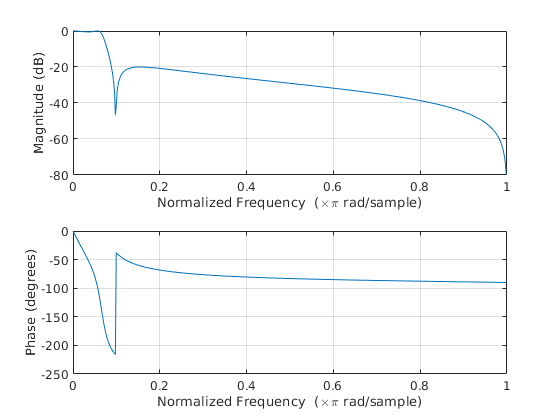

y4n=filter(b4,a4,xn);
y4k=abs(fft(y4n));
figure();
freqz(b4,a4);

Por último se grafican la señal filtrada y su espectro

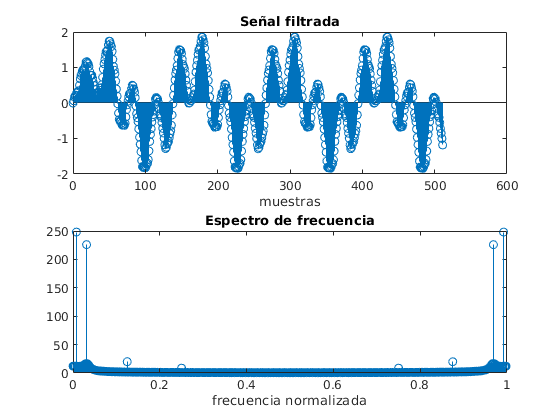

figure()
subplot(2,1,1)
stem(n,y4n);
xlabel('muestras')
title('Señal filtrada');
subplot(2,1,2);
stem(k,y4k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

Compare el desempeño de los filtros. Analice en el dominio de la frecuencia cerca de la frecuencia de corte.

¿Cómo se puede determinar cuál de los cuatro filtros es mejor?